# Joint Compression and Error Recovery

In this matlab code, I will demonstrate the joint compression and error recovery using compressive sensing, which is proposed in my recent work.  This method is computationally efficient because both compressive and error recovery can be achieved by performing single matrix vector multiplication. The details are here:[https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9373354](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9373354)

To show this application, I take the example of electrocardigram (ECG) signals. Now let's load a ECG signal signal of length **N**.

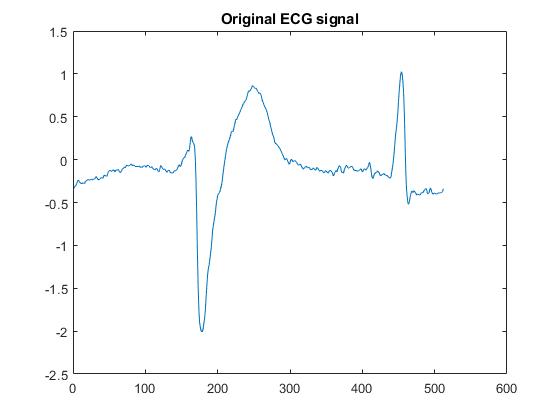

N=512;  % signal length
w=2;   % w^th signal window of size N
load mit200
x=ecgsig(1+(w-1)*N:w*N,1);  
plot(x) ;
title("Original ECG signal")

Construction of a joint compression and error recovery matrix. **M** is the signal dimension after compression and **L** is the signal dimension after adding redundancy for error recovery. The joint compression and error recovery matrix is denoted as **G**.

M=280; L=380;
B=sign(randn(M,N)); % A and B can be any matrix as far as they satisfy the compressive sensing properties
A=sign(randn(L,M));
G=A*B; 
G=normc(G); % Normalize the columns of the matrix G

Now perform the joint compression and error recovery encoding. One can store the precomputed matrix **G**

y=G*x;
%plot(y);

We can assume the interference and error as vector **e. **The received signal is given as **yrx**. **rho** is the number of sysbols  corrupted by the noise  in the vector **y**.

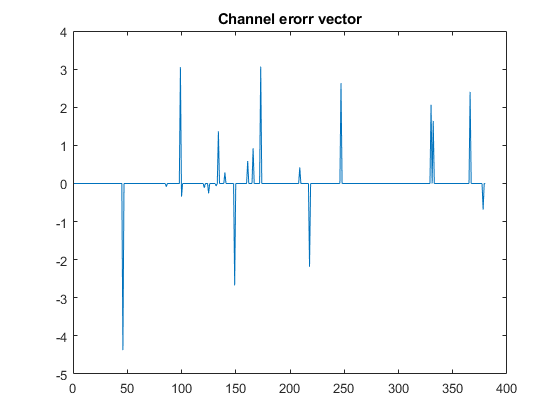

rho=20; % Corrupt the rho number of symbols
e=zeros(L,1); 
sigma=2; % The value of sigma does not play any role one can increase it
e(randperm(L,rho))=sigma*randn(rho,1);
plot(e);
title("Channel erorr vector")

yrx=y+e;
%plot(yrx);

Now at the receiver the first task is to recover error. For error recovery,  projection method is used.

P=A*inv(A'*A)*A';
P_orth=eye(L)-P;
e0=P_orth*yrx;
Vec_ones = ones([2 * L, 1]);
Vec_low = zeros([2 * L, 1]);
Vec_high = inf([2 * L, 1]);

ssOpt=optimoptions('linprog', 'Algorithm', 'interior-point');

z_hat=linprog(Vec_ones,[],[], [P_orth -P_orth], e0, Vec_low, Vec_high,ssOpt);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in feasible directions, to within the selected value of the
function tolerance, and constraints are satisfied to within the selected value of the constraint tolerance.



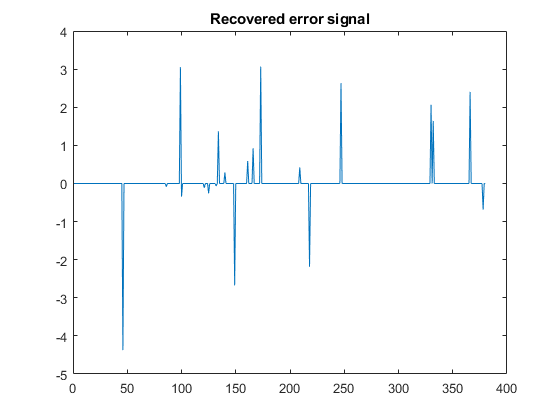


e_esti=z_hat(1:L)-z_hat(1+L:end);
plot(e_esti);
title("Recovered error signal")

Remove the estimated error from the recived signal.

y_hat=yrx-e_esti;

Final step signal reconstruction.

## l1-recovery using linear program

psi=wmpdictionary(N,'lstcpt',{'dct',{'sym4',4},{'db8',5},{'rbio4.4',5}});
phi_rec=A'*G*psi;
x0=A'*y_hat;
NN=size(psi,2);
% transfering l1 minimization into linear program
Vec_ones = ones([2 * NN, 1]);
Vec_low = zeros([2 * NN, 1]);
Vec_high = inf([2 * NN, 1]);

ssOpt=optimoptions('linprog', 'Algorithm', 'interior-point');

z_hat=linprog(Vec_ones,[],[], [phi_rec -phi_rec], x0, Vec_low, Vec_high,ssOpt);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in feasible directions, to within the selected value of the
function tolerance, and constraints are satisfied to within the selected value of the constraint tolerance.



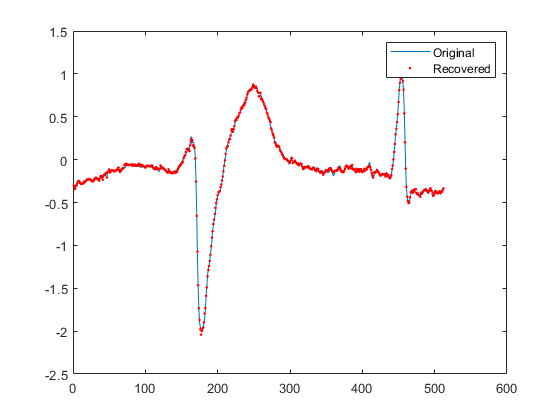


xp_hat=z_hat(1:NN)-z_hat(1+NN:end);

x_hat=psi*xp_hat;
figure;
plot(x);
hold on;
plot((x_hat), 'r.');
legend('Original', 'Recovered');


disp("Mean square error is")

Mean square error is


mse(x,x_hat)

ans = 2.8247e-04